**What do the following have in common?...**

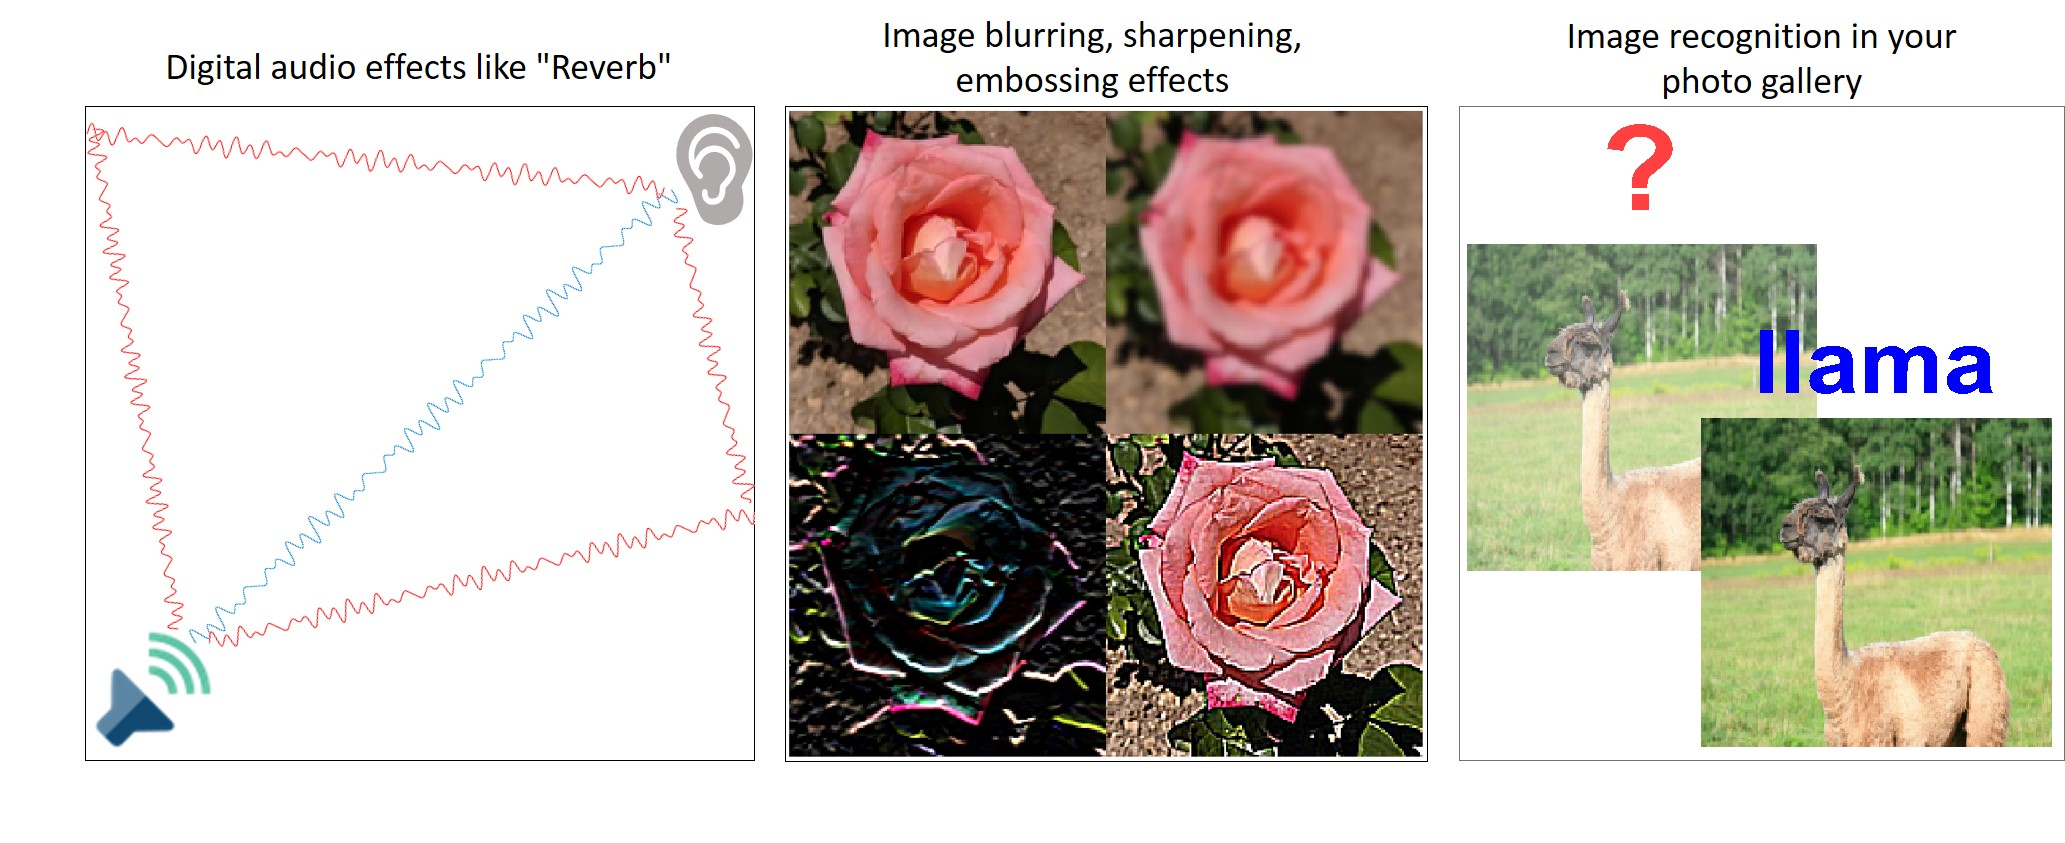

**... it's Convolution! **

# Convolution: Basics

**Suggested Prework**

[MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html) – a free two-hour introductory tutorial to learn the essentials of MATLAB.

## What is Convolution?

The convolution of two continuous signals is another continuous signal. The value at some time `t `is defined as the integral of the products of the two input signals, where one of the signals has been shifted in time by `t` and flipped.

                                    
$$w\left(t\right)=\int_{-\infty }^{\infty } u\left(\tau \right)v\left(t-\tau \right)d\tau$$
  

Let's visualize this process with two simple pulse signals.

% Set up the time step and time (X) axis data.
ts = 1/1000;             % Time step
t = -3:ts:3;             % Time vector

Visit the documentation to learn more about the inputs to these functions: [rectpuls](https://www.mathworks.com/help/signal/ref/rectpuls.html), [tripuls](https://www.mathworks.com/help/signal/ref/tripuls.html)

**Task. **Use the sliders and drop-down lists to set different parameters for the signals. Click **Show convolution** to view the convolution process and its result. 

u  = rectpuls(t,1) *1 ; % The first slider sets the width, the second slider scales the amplitude
v  = tripuls(t,1) *1 ; % The first slider sets the width, the second slider scales the amplitude

 

animateConvolution(u,v,ts,t,-2);

This process is also called linear convolution.

  **Try**

- Change `u` to a rectangular pulse of width `1.5` and amplitude `1`. 

- Change `v` to a triangular pulse of width `1.5` and amplitude `1`.

- Swap the `u` and `v` signal settings`.`

- Set `u` and `v` both to triangular pulse with different widths and amplitudes.

- Use the third input to set the signal's skewness when using the triangular pulse signals.

 ***Reflect***

- *Does the order of inputs matter? Is convolution commutative?*

- *Describe your general observations about the convolution output *`w`* compared to the inputs *`u`* and *`v`.

## Compute Convolution

The animation above illustrates continuous convolution, which is defined as an integral. This was achieved by approximating a continuous result based on a discrete summation. Discrete convolution is defined by this summation:

                                    
$$w\left(k\right)=\sum_n u\left(n\right)\cdot v\left(k-n\right)$$


You can use the [`conv`](https://www.mathworks.com/help/releases/R2020a/matlab/ref/conv.html) function to compute the discrete convolution of two input sequences or discrete signals.

Let us define two 1-D discrete signals and convolve them using the `conv` function. 

**Task. **Use the sliders and drop-downs to set different parameters for the two input signals.

figure("Position",[0 0 1200 350]);

L = 151;                   % length of input sequences u and v. Keep it odd for simplicity
n = -(L-1)/2:(L-1)/2;      % X axis data for the signals

u  = rectpuls(n,80);
stem(n,u,"r.")
v  = tripuls(n,90);
stem(n,v,"b.")

We use the `conv` function to convolve two vectors in MATLAB.

w  =  conv(u, v);
disp("Output length = " + length(w))
nOut = -(L-1):(L-1);
stem(nOut,w,"g.");

 ***Reflect***

- *How is the length of convolution output related to the length *`L`* of the two input signals? *

- *What do you think would happen if the input sequences had different lengths? Say, *`M`* and *`N`*, instead of *`L`*.*

## Compute Convolution using DFT

The** convolution theorem** implies that convolution in time domain is equivalent to multiplication in the frequency domain.

To convolve two signals, 

- compute the point-wise product of their respective DFTs

- compute the inverse DFT of this product

[FFT](https://www.mathworks.com/help/matlab/ref/fft.html) is an efficient algorithm to compute the DFT. [Here](https://www.mathworks.com/matlabcentral/fileexchange/71001-fft-easy-with-live-editor) is a live script example illustrating use of `fft`.

wDFT = ifft(fft(u) .* fft(v)); 
stem(n,wDFT,"b.")                         % Output has the same length (L) as the input signals u and v

This process results in what is known as circular convolution.

 ***Reflect*** 

- *Compare the length of *`wDFT`* with the length of *`w`*. Why are they different?*

- *Why is this called "circular" convolution?*

## Circular Convolution $\iff$ Linear Convolution

Why compute convolution via DFT/FFT? The combination of the convolution theorem and the fast Fourier transform (`fft`) can make this operation faster for very long sequences. However, we are often only interested in computing linear convolution, not circular convolution.

Can you get linear convolution output via circular convolution? Yes, under certain conditions, circular convolution is equivalent to linear convolution. 

**Task.** Observe and run the code below to learn more.

K = length(u) + length(v) - 1;
upad = [u zeros(1,K - length(u))];
vpad = [v zeros(1,K - length(v))];
wCirc = ifft(fft(upad) .* fft(vpad));
stem(nOut,wCirc,"g.")

You can also use the [cconv](https://www.mathworks.com/help/signal/ref/cconv.html) function to do the same computation as above. By default, the `cconv` function returns the same output as `conv.`

wCirc = cconv(u,v);
stem(nOut,wCirc,"g.")
wLin = conv(u,v);

Verify whether the two convolution outputs (`wLin` and `wCirc`) are truly equal.

display("Norm of difference between conv and cconv outputs = " + norm(wLin-wCirc))

You can specify a length `n` as the third input to `cconv` to perform **modulo-n** **circular** convolution. 

wCirc = cconv(u,v,length(u)); % Output length same as length(u)
stem(n,wCirc,"b.") 

 ***Reflect***

- *What are the conditions under which the circular and linear convolution results are equivalent?*

- *What is the default length used in the *[*cconv*](https://www.mathworks.com/help/signal/ref/cconv.html)* function if you do not specify the third input? (Use the documentation to find out).*

## **Practice Problem**

The code below generates two signals. Study this code and perform the tasks below to complete this section.

fs = 10000;                   % Sampling frequency, increase this to increase number of samples in the signals

% Generate a sine wave
t = -3:1/fs:3;
u = sin(4*pi*t);
plot(t,u)

% Generate a parabolic signal from a unit step
t2 = -2:1/fs:2;
unitstep = (t2 >= 0);
v = t2.^2 .* unitstep; 
plot(t2,v)

**Task.** Compute the full-length output of linear convolution of $u\left(t_1 \right)$ and $v\left(t_2 \right)$.

**NOTE:** To get an approximate for the continuous convolution output using discrete signals, you must normalize (divide) the convolution output by `fs`*.*

**Task.** Replace the empty signal in the text box to plot the output of convolution computed above.

% Plot the output of convolution by replacing the code in the text box.
T = -5:1/fs:5;           
plot(T, nan(size(T)));

**Task. **Follow the instructions in the comments to compute the circular convolution of `u` and v using `fft` and `ifft` to get the linear convolution equivalent output and plot the result.

% Compute the output length of full linear convolution K, using M and N as defined below.
M = length(u);
N = length(v);
K = 0;

% Zero-pad the signals u and v to make them the required lengths for computing convolution.
upad = [u zeros(1,K - M)];        % pad u
               % pad v

% Use fft and ifft to compute circular convolution output.
  

% Compute the length of the output. Is it the expected length?
  

% Plot the output of the convolution against the time vector T.
plot(T,nan(size(T)),"g") 

Upon completion, your convolution plots should look like this:

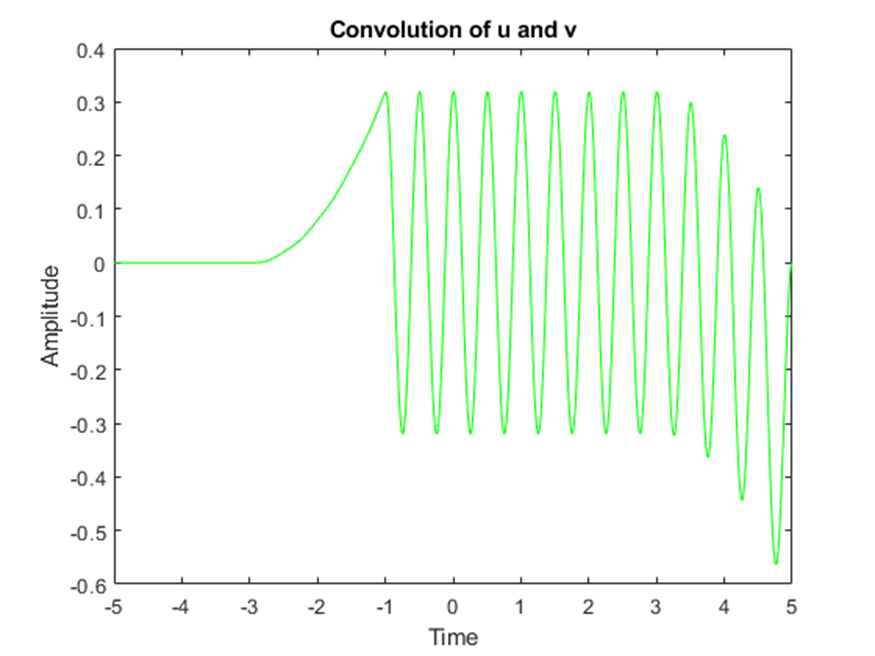

## 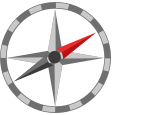Further Exploration

### Polynomial Multiplication

What has this got to do with convolution? Let's find out!

    $\textrm{p1}=3x^3 +4x^2 +5x+1$;    

    $\textrm{p2}=4x^2 +2$;

Create vectors containing the coefficients of $\textrm{p1}$ and $\textrm{p2}$.

p1 = [3 4 5 1];
p2 = [0 4 0 2];

**Task.** Enter code to convolve $\textrm{p1}$ with $\textrm{p2}$.

 ***Reflect***

- Observe the convolution output. Work out the polynomial multiplication on paper and check whether the coefficients match the output of convolution. If they do, can you explain why?

## Helper Functions

Function for creating the convolution animation.

function animateConvolution(f,h,ts,t,t0)
% ANIMATECONVOLUTION(F,H,Ts,T,T0) illustrates the process of convolving two
% signal F and H given the corresponding time vector T, a sampling time of
% Ts, and an initial starting time of T0.

fs = 1/ts;
Cind = find(t == t0);   % Index of starting point in t
h_center = t0;

% Shift signal to extreme and flip
h = circshift(h,find(t==0) - Cind);
h = fliplr(h);

% Initialize plots for animation
figure("Position",[0 0 1200 350]);
title("Continuous Convolution")
xlabel("Time (t and \tau)")
ylabel("Amplitude")

% Plot the first iteration of signals to set up all the properties.
hold on
p0 = plot(t,f,"r","LineWidth",1.2);
p1 = plot(t,h,"b","LineWidth",1.2);
p2 = plot(t0,sum(f.*h)/fs,"g-","LineWidth",1.5);
p3 = area(t,f.*h,"FaceColor","g","FaceAlpha", 0.2,"EdgeColor","k","LineWidth", 1,"ShowBaseLine","off");
p4 = xline(t0, ":k");
legend("u(\tau)","v(t-\tau)","Convolution output w(t)","Area under u(\tau)*v(t-\tau)","Center of v","Location","bestoutside")
xlim([t(1) t(end)]);

% Loop to update plots to visualize the process and result of convolution.
K = fs/20;  % steps to shift the signal in each iteration

while h_center <= abs(t0)       
    % Convolve
    h = circshift(h,K);             % shift the second signal
    prod = f.*h;                    % compute product of the signals
    y = sum(prod)/fs;               % compute integral of product i.e. area under the product    
    h_center = h_center + K/fs;
    
    % Update plots
    p1.YData = h;
    p2.XData = [p2.XData, h_center];
    p2.YData = [p2.YData, y];    
    p3.YData = prod;
    p4.Value = h_center;
    drawnow  
end
hold off

end